% % define function
% fun1=@(x,y,z) (x.^2+y.^2).^2-(x.^3+y.^3).*(z/4-z.^2).^(1/2);
% dt=@(z)0.25*(z/4-z.^2).^(1/2);
% helper=@(x,y,z,dt)fun1(x+dt, y+dt, z);
% fun=@(x,y,z)helper(x,y,z,dt(z));
% 
% % code
% [x,y,z] = meshgrid(linspace(-3, 3, 40));
% v = fun(x,y,z);
% v = real(v); % deal with complex values
% [faces, verts] = isosurface(x,y,z,v,0);
% t = triangulation(faces, verts);
% stlwrite(t, 'test.stl');
% disp('done');

clear;clc;
opt_data = load("../opt/dvar_synth_3dim.mat");
opt_data = opt_data.vect;

n = 0;
zc = 0;

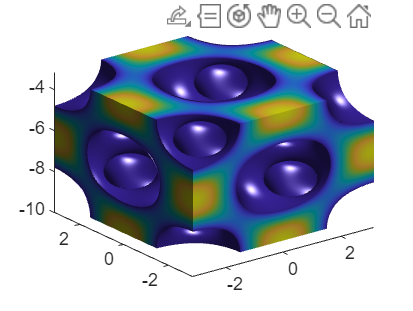

FacesUnion = [];
VertsUnion = [];
for i=1:size(opt_data,1)
    if mod(i,30) == 1
        zc = zc+1;
        n = 0;
    end
    [faces, verts] = TPMS_surface(opt_data(i,1),opt_data(i,2),opt_data(i,3),opt_data(i,4),opt_data(i,5),opt_data(i,6),n,0,zc);
    if i == 1
        IndexEnd = 0;
    else        
        IndexEnd = max(max(FacesUnion));
    end

    FacesUnion = [FacesUnion;faces+IndexEnd];
    VertsUnion = [VertsUnion;verts];
    n=n+1;

    t = triangulation(FacesUnion, VertsUnion);
    stlwrite(t, 'testNetwork.stl');

    t2 = triangulation(faces, verts);
    stlwrite(t2, 'single.stl');

end



% alpha1 = 0;
% alpha2 = 1;
% alpha3 = 0;
% t1 = 0;
% t2 = -0.5;
% t3 = 0;
% 
% x = [-0.5:0.01:0.5]*2*pi;
% y = [-0.5:0.01:0.5]*2*pi;
% z = [-0.5:0.01:0.5]*2*pi;
% [X,Y,Z] = meshgrid(x,y,z);
% 
% F1 = cos(X) + cos(Y) + cos(Z)+ t1;
% F2 = cos(X).*cos(Y).*cos(Z) - sin(X).*sin(Y).*sin(Z) + t2;
% F3 = 8*cos(X).*cos(Y).*cos(Z)+cos(2*X).*cos(2*Y).*cos(2*Z)-(cos(2*X).*cos(2*Y)+cos(2*Y).*cos(2*Z)+cos(2*Z).*cos(2*X))+t3;
% Fmerge =@(X,Y,Z) alpha1*4*F1+alpha2*4*F2+alpha3*F3;
% fun = 0.576*4*(cos(X)+cos(Y)+cos(Z)+0.146)+0.364*4*(cos(X).*cos(Y).*cos(Z)-sin(X).*sin(Y).*sin(Z)+-0.0547)+0.0597*(8*cos(X).*cos(Y).*cos(Z)+cos(2*X).*cos(2*Y).*cos(2*Z)-(cos(2*X).*cos(2*Y)+cos(2*Y).*cos(2*Z)+cos(2*Z).*cos(2*X))+-0.213);
% 
% v = Fmerge(x,y,z);
% v = real(v); % deal with complex values
% [faces, verts] = isosurface(x,y,z,v,0);
% 
% v1 = Fmerge(x,y,z);
% [faces1, verts1] = isosurface(x+5*pi,y,z,v1,0);
% 
% faces3 = [faces;faces1+49614];
% verts3 = [verts;verts1]
% t = triangulation(faces3, verts3);
% 
% stlwrite(t, 'test.stl');
% disp('done');



function [faces, verts]=TPMS_surface(alpha1,alpha2,alpha3,t1,t2,t3,Xc,Yc,Zc)
% alpha1 = 0.411;
% alpha2 = 0.144;
% alpha3 = 0.445;
% t1 = -0.120;
% t2 = -0.349;
% t3 = -0.359;

x = [-0.5:0.01:0.5]*2*pi;
y = [-0.5:0.01:0.5]*2*pi;
z = [-0.5:0.01:0.5]*2*pi;
[X,Y,Z] = meshgrid(x,y,z);

F1 = cos(X) + cos(Y) + cos(Z)+ t1;
F2 = cos(X).*cos(Y).*cos(Z) - sin(X).*sin(Y).*sin(Z) + t2;
F3 = 8*cos(X).*cos(Y).*cos(Z)+cos(2*X).*cos(2*Y).*cos(2*Z)-(cos(2*X).*cos(2*Y)+cos(2*Y).*cos(2*Z)+cos(2*Z).*cos(2*X))+t3;
Fmerge =@(X,Y,Z) alpha1*4*F1+alpha2*4*F2+alpha3*F3;
% fun = @(X,Y,Z)0.576*(cos(X)+cos(Y)+cos(Z)+0.146)+0.364*(cos(X).*cos(Y).*cos(Z)-sin(X).*sin(Y).*sin(Z)+-0.0547)+0.0597*(8*cos(X).*cos(Y).*cos(Z)+cos(2*X).*cos(2*Y).*cos(2*Z)-(cos(2*X).*cos(2*Y)+cos(2*Y).*cos(2*Z)+cos(2*Z).*cos(2*X))+-0.213);

v1 = Fmerge(x,y,z);
[faces, verts] = isosurface(X+2*pi*Xc,Y-2*pi*Yc,Z-2*pi*Zc,v1,0);
[facesc, vertsc] = isocaps(X+2*pi*Xc,Y-2*pi*Yc,Z-2*pi*Zc,v1,0);
faces = [faces;facesc+length(verts)];
verts = [verts;vertsc];

figure(1001)
isosurface(X+2*pi*Xc,Y-2*pi*Yc,Z-2*pi*Zc,v1,0)
isocaps(X+2*pi*Xc,Y-2*pi*Yc,Z-2*pi*Zc,v1,0)

end